clear, clc
close all
% datadir = '/Volumes/zhou/A_arousal_analysis/data';
datadir = 'G:\A_arousal_analysis\data';
load(fullfile(datadir, 'Arousal_rating_study2.mat'))
load(fullfile(datadir, 'fig_cols.mat'))
cols = cols./255;

## behavioral rating

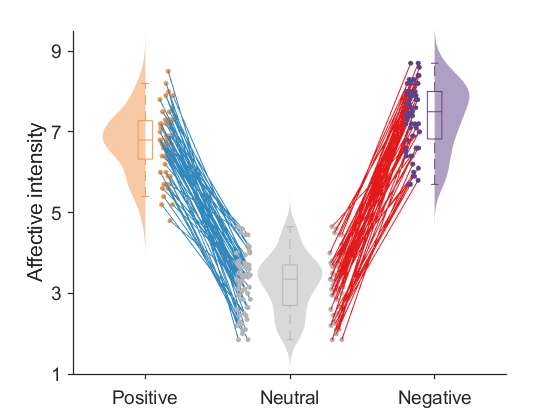

for subj = 1:63
    subneutral = arousal_rating(category==2,subj);
    neutral_rating(subj, 1) = mean(subneutral);
    positive = arousal_rating(category==1, subj);
    positive_rating(subj, 1) = mean(positive);
    negative = arousal_rating(category==3,subj);
    negative_rating(subj, 1) = mean(negative);
end


dataConditions = {positive_rating, neutral_rating, negative_rating};
conditionLabels = {'Positive', 'Neutral', 'Negative'};

righthigher = dataConditions{1} < dataConditions{2};
linecolors{1} = zeros(length(righthigher), 3);
linecolors{1}(righthigher, :) = repmat([0.8902    0.1020    0.1098], sum(righthigher), 1);
linecolors{1}(~righthigher, :) = repmat([0.1961    0.5333    0.7412], sum(~righthigher), 1);

righthigher = dataConditions{2} < dataConditions{3};
linecolors{2} = zeros(length(righthigher), 3);
linecolors{2}(righthigher, :) = repmat([0.8902    0.1020    0.1098], sum(righthigher), 1);
linecolors{2}(~righthigher, :) = repmat([0.1961    0.5333    0.7412], sum(~righthigher), 1);

plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.08, 'connectwidth', 0.5, 'colors', cols(1:3,:), 'linecolors',linecolors);
%plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.1, 'connectwidth', 0.5, 'colors', cols(1:3,:));

ylabel('Affective intensity');
set(gca,'YLim', [1 9.5], 'ytick',1:2:9, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)


% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 4.5 3.5]);
% print('-dtiff', 'A_arousal_rating_study2.tif', '-r400')
% 
% close all

load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'))
load(fullfile(datadir, 'A_arousal_validation_connectivity_latest.mat'))
negative_PE = [ones(63,1), negative_FC] * b_pls;
positive_PE = [ones(63,1), positive_FC] * b_pls;
neutral_PE = [ones(63,1), neutral_FC] * b_pls;
clear negative_FC positive_FC neutral_FC

## PAES expression

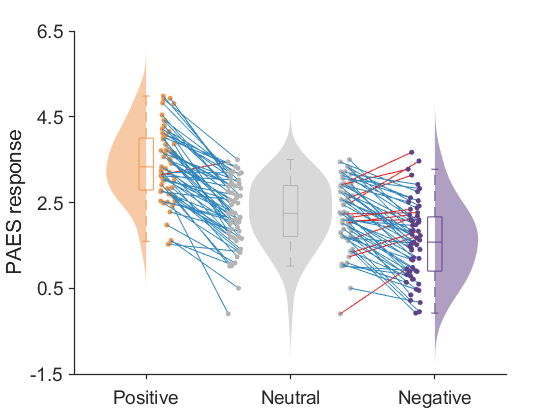

dataConditions = {positive_PE(:,1), neutral_PE(:,1), negative_PE(:,1)};
conditionLabels = {'Positive', 'Neutral', 'Negative'};

righthigher = dataConditions{1} < dataConditions{2};
linecolors{1} = zeros(length(righthigher), 3);
linecolors{1}(righthigher, :) = repmat([0.8902    0.1020    0.1098], sum(righthigher), 1);
linecolors{1}(~righthigher, :) = repmat([0.1961    0.5333    0.7412], sum(~righthigher), 1);

righthigher = dataConditions{2} < dataConditions{3};
linecolors{2} = zeros(length(righthigher), 3);
linecolors{2}(righthigher, :) = repmat([0.8902    0.1020    0.1098], sum(righthigher), 1);
linecolors{2}(~righthigher, :) = repmat([0.1961    0.5333    0.7412], sum(~righthigher), 1);

plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.08, 'connectwidth', 0.5, 'colors', cols(1:3,:), 'linecolors',linecolors);
%plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.1, 'connectwidth', 0.5, 'colors', cols(1:3,:));

ylabel('PAES response');
set(gca,'YLim', [-1.5 6.5], 'ytick',-1.5:2:6.5, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)


% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 4.5 3.5]);
% print('-dtiff', 'A_PAES_response_study2.tif', '-r400')
% close all

## NAES expression

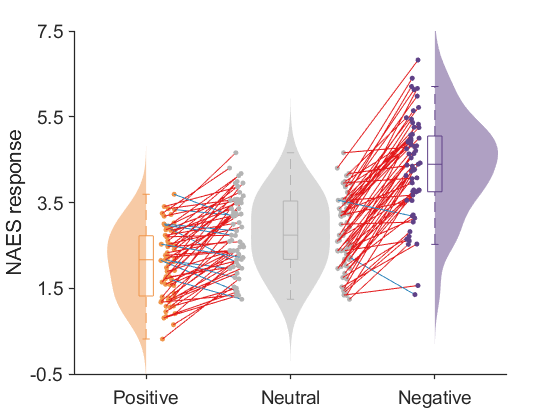

dataConditions = {positive_PE(:,2), neutral_PE(:,2), negative_PE(:,2)};
conditionLabels = {'Positive', 'Neutral', 'Negative'};

righthigher = dataConditions{1} < dataConditions{2};
linecolors{1} = zeros(length(righthigher), 3);
linecolors{1}(righthigher, :) = repmat([0.8902    0.1020    0.1098], sum(righthigher), 1);
linecolors{1}(~righthigher, :) = repmat([0.1961    0.5333    0.7412], sum(~righthigher), 1);

righthigher = dataConditions{2} < dataConditions{3};
linecolors{2} = zeros(length(righthigher), 3);
linecolors{2}(righthigher, :) = repmat([0.8902    0.1020    0.1098], sum(righthigher), 1);
linecolors{2}(~righthigher, :) = repmat([0.1961    0.5333    0.7412], sum(~righthigher), 1);

plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.08, 'connectwidth', 0.5, 'colors', cols(1:3,:), 'linecolors',linecolors);
%plotPairedComparison(dataConditions, conditionLabels, 'dotsize', 10, 'densityscalefactor', 0.1, 'connectwidth', 0.5, 'colors', cols(1:3,:));

ylabel('NAES response');
set(gca,'YLim', [-0.5 7.5], 'ytick',-0.5:2:7.5, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)


% set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 4.5 3.5]);
% print('-dtiff', 'A_NAES_response_study2.tif', '-r400')
% close all